# Técnicas de procesamiento de señales y datos (MUIE)

## Ejercicio práctico bloque 4.1.4. Efecto del tamaño de la ventana de señal (v3.0)

### Objetivo

El objetivo de este ejercicio es la comprension del impacto del tamaño de ventana de análisis en el espectro calculado de las señales. Disculpad que a veces no aparezcan tildes, pero al cambiar de version de matlab, hay un bug que no permite escribirlas.

### Desarrollo

Se dispone de una señal x(t), sinusoidal de frecuencia 1 Hz y duración variable. Implemente un script en Matlab que realice las siguientes acciones:

- Borre variables, figuras y ventana de comandos:

clear all;
close all force;
clc;

- Tras definir las caracteristicas de x(t), genere a partir de ella una señal discreta x[n] muestreando x(t) a una frecuencia de 10Hz. Defina la longitud (duracion) de la señal x[n] a partir del numero de periodos de quiera considerar (modifique ese valor para evaluar el efecto de usar 3, 6, 9, 12, etc. periodos). Calcule el módulo de la FFT y dibujelo (use 2048 como tamaño de la FFT, y no es necesario que normalice como se ha contado en clase para ver el efecto). Escriba en un comentario breve en el código sus observaciones y justificación, incluyendo un comentario sobre las ventajas e inconvenientes de usar tamaños de ventana grandes o pequeños. 

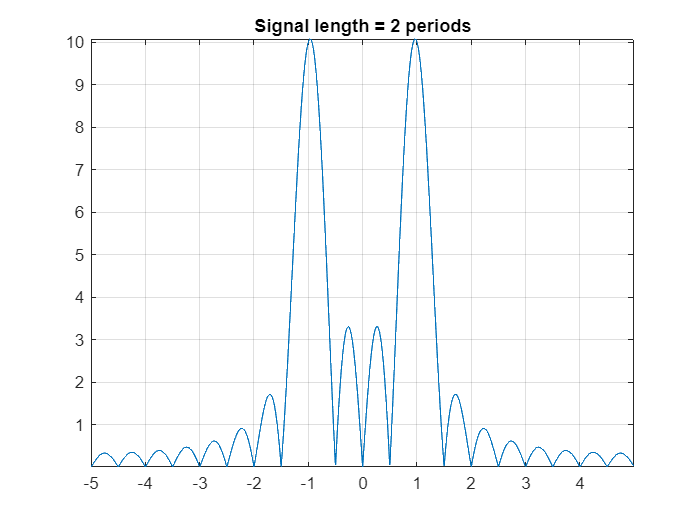

% x(t) signal characteristics
f            = [ 1 ];
amplitude    = [ 1 ];
phase        = [ 0 ];
fs           = 10;

% FFT analysis parameters
fftSize      = 2048;
fftSize_2    = fftSize/2;

% Define the number of periods to use (that will be related to the signal
% duration, which is equal to the window length)
numPeriods   = 2; % Change this value to 3, 6, 9, 12, ...
    
% Generate the signal
timeDuration = numPeriods * 1 / f;
[ x, numSamples, timeIndexes ] = generateSignal(fs, timeDuration, f, amplitude, phase);

% Calculate the fft without normalization (not needed to see the effect)
fftX = fft(x, fftSize); 
plot([fs * (-fftSize_2:(fftSize_2-1)) / fftSize], abs(fftshift(fftX)));
title(['Signal length = ', num2str(numPeriods), ' periods' ]);
%xlim([-fs/2 fs/2]);
grid on
axis tight

% Observaciones y justificación: 
% + Piense y discuta si la forma que observa es coherente con lo visto en teoria 
%   (¿si la señal es sinusoidal, ¿cual deberia ser su espectro?)
% + Piense y discuta la justificacion de la anchura del lobulo principal
% + Piense y discuta lo que sucede cuando se incrementa la duracion de la señal
% + Piense y discuta si podriamos utilizar cualquier numero de periodos 
%   (relacionandolo con el tamaño de la FFT)
% + Piense y discuta las ventajas/inconvenientes de usar ventanas mayores o 
%   menores (no solo en cuanto el analisis, sino en cuanto al coste
%   computacional)
% + Piense y discuta si podemos utilizar ventanas muy largas cuando
%   la señal no es estacionaria




- Puede mejorar el codigo incluyendo la variacion del tamaño de señal en un bucle y pintando cada espectro en un subplot diferente.

% ...